clear;
load processed_thruster_data.mat

Demonstration of how to use the obtained system with transformation (look at y-axis)

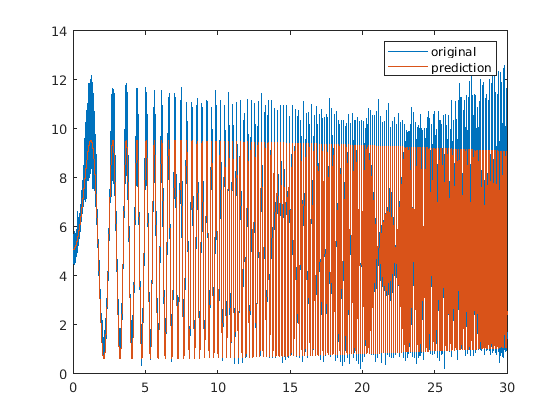

dataOriginal = load('thruster_data.mat');
models = load('models.mat'); 

% this function transforms data to be usable for model and then transforms
% the model's response back to the original domain
% supplying original, unshifted data!
transformAndPredict(dataOriginal.data_sine, time_sine, models.M_tfsrivc, u_shift, y_shift);

function transformAndPredict(data_original, time, model, u_shift, y_shift)
    u_shifted = data_original.u - u_shift;
    y = lsim(model, u_shifted, time);
    y_shifted = y + y_shift;
    plot(time, data_original.y, time, y_shifted);
    legend('original', 'prediction');
end